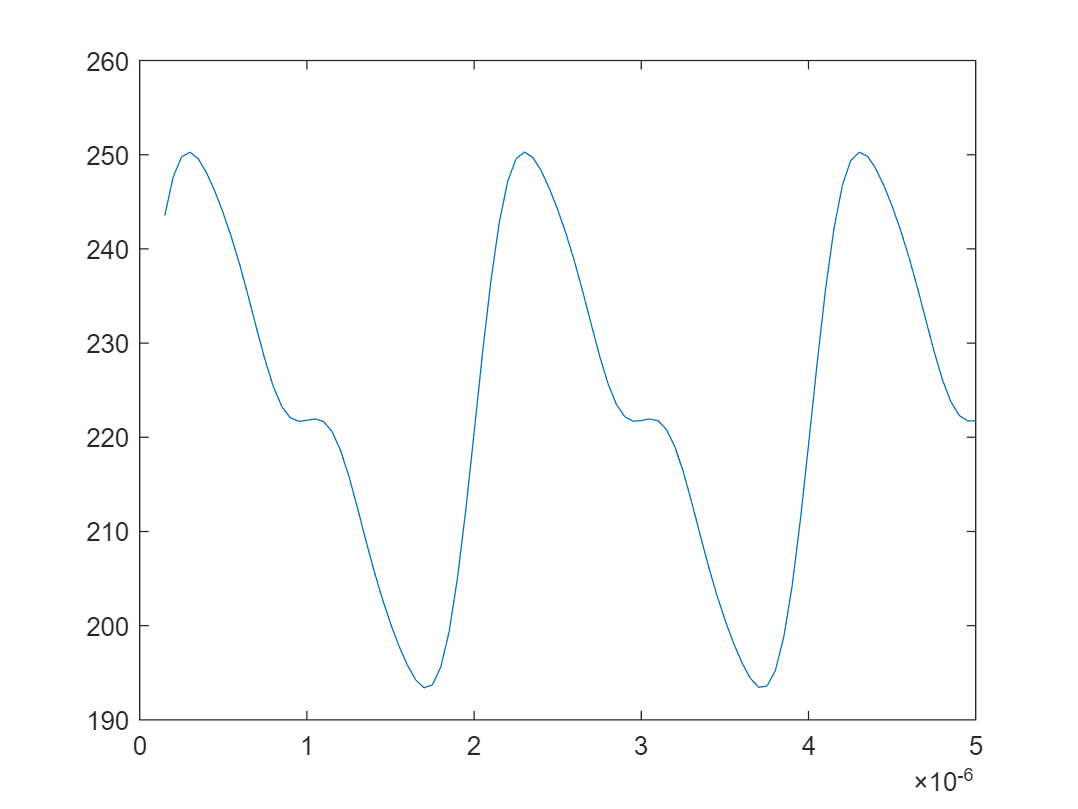

clear
clc
Fs = 5E6;
Fin = 51/512*Fs;
win = 2*pi*Fin;
timeoffset = 150e-9;
t = linspace(timeoffset,51/Fin + timeoffset,512*4);

R_mag = [46.92, 24.24, 17.74, -1.88, 0.49];
Sine = [ones(size(t)); sin(win.*t); sin(2*win.*t); sin(3*win.*t); sin(4*win.*t)];
R = db2mag(R_mag) * Sine;

figure
plot(t,R);
xlim([0,5E-6])